# E3DSB miniprojekt 4

Team 4

202200284 - Danni Raetzel

201900368 - Martin Armose

### **Indledning og formål**

Denne rapport fokuserer på udviklingen af et 2. ordens IIR lavpasfilter og beregning af frekvens. Filteret vil blive anvendt på simulerede støjfyldte signaler for at se om vi får den ønskede effekt. Med støj menes der at signalet indeholder højere harmoniske signaler, som er uønsket da det kan påvirke vores beregning af frekvensen. Formålet med at filtrere et støjfyldt signal, er at hurtigere og mere sikkert kunne beregne frekvensen. 

Målet med rapporten er at designe og teste en nøjagtig og hurtig frekvensmåler. Herunder design og analyse af 2. ordens IIR-filter med DFT, zero crossing og interpolation. 

Vi skal vise at vi kan finde grundfrekvensen på 50.1111 Hz med en maksimal afvigelse på $+-10$mHz

### Plotning af de to signaler

close all; clear; clc % oprydning
% Importerer data
loadedData = load('signal_IEC60255_50_1111Hz.mat');

% Antag structen i filen hedder 'myStruct'
signal = loadedData.signal;

% Assign felterne i structen til variabler
x1 = signal.x1;
x2 = signal.x2;
fs = signal.fs;

% Vis data
disp(['x1 size: ', num2str(length(x1))]);

x1 size: 5000


disp(['x2 size: ', num2str(length(x2))]);

x2 size: 5000


disp(['Samplingfrekvens fs: ', num2str(fs), ' Hz']);

Samplingfrekvens fs: 10000 Hz


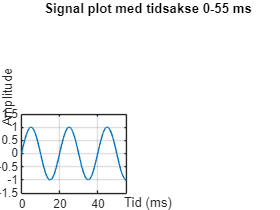


% Længde af signalet
N = length(x1);

% Samplingperiode (invers af fs)
Ts = 1 / fs; % i sekunder

% Tidsvektor (0 til N-1 multipliceret med samplingperiode)
t = (0:N-1) * Ts; % i sekunder


% Plot af hele signalet
figure;
plot(t * 1000, x1); % t konverteres til millisekunder
xlabel('Tid (ms)');
ylabel('Amplitude');
title('Signal plot med tidsakse 0-55 ms');
grid on;

% Begrænsning af tidsaksen til 0-55 ms
xlim([0, 55]); % i millisekunder

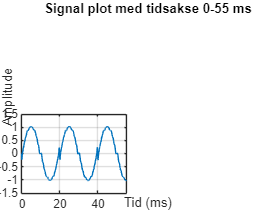


% Plot af hele signalet
figure;
plot(t * 1000, x2); % t konverteres til millisekunder
xlabel('Tid (ms)');
ylabel('Amplitude');
title('Signal plot med tidsakse 0-55 ms');
grid on;

% Begrænsning af tidsaksen til 0-55 ms
xlim([0, 55]); % i millisekunder

Det er tydeligt at se at det kan give problemer at beregne en korrekt frekvens når støjen skaber utilsigtede crossovers. For at beregne en korrekt frekvens vil vi gerne have et sinussignal som det vi har i det øverste plot. 

### Tids- og frekvensanalyse

Vi må maksimalt have en afvigelse på $\pm 10\textrm{mHz}$, det betyder at frekvensopløsningen skal være$\Delta f\le 10\textrm{mHz}$.

Det frekvensspektrum der giver mening at analysere er op til nyquist frekvensen som er $f_{\textrm{nyquist}} =\frac{f_{\;s} }{2}=5000\textrm{Hz}$.

Frekvensopløsningen i en frekvensanalyse fortæller os hvad den mindste forskel mellem to frekvenser, der kan skelnes imellem. Formlen for frekvensopløsningen er:


$$\Delta f=\frac{f_s }{N}=\frac{10\textrm{kHz}}{5000}=2\textrm{Hz}$$


Så vi kan først skelne mellem signaler når der er mindst 2Hz imellem dem. Med hurtig hovedregning betyder det at vi ligger 200 gange over den nødvendige frekvensopløsning. For at opfylde kravet til frekvensopløsningen skulle vi altså have en højere samplingfrekvens og/eller et længere signal (flere samples).

Hvis vi kigger i vores workspace i matlab, så har vi samples der svarer til at halvt sekund $\frac{\textrm{x1}}{f_s }=\frac{5000}{10000}=0\ldotp 5s$

Vi definerer forskellige værdier:

% Parametre
Ndft = 5000;      % Antal samples / antal frekvensbins
n = 0:Ndft-1;     % Antal samples i tidsdomænet
k = 0:Ndft-1;     % antal bins i frekvensdomænet 
fs = 10000        % Samplingfrekvensen [Hz]

fs = 10000

T0 = 1 / fs       % Sampleperiode [s]

T0 = 1.0000e-04

t = (0:N-1) * Ts; % i sekunder
f = fs*k/Ndft;    % Ser på grundfrekvenserne 
f_akse = (0:N/2-1) * (fs / N); % Frekvensakse for positiv del af spektret

Vi foretager fft

X1 = fft(x1,Ndft);
X2 = fft(x2,Ndft);

Amplitude- og faseresponset findes

X1_mag_dB = 20 * log10(abs(X1(1:N/2)));
X1mag = abs(X1)*(2/N); % Vi ganger med 2/N for at få korrekte amplitude
X1mag(1)=X1mag(1)/2;   % Finder korrekt DC værdi

X2mag = abs(X2)*2/N;
X2mag(1)=X2mag(1)/2;
X2_mag_dB = 20 * log10(abs(X2(1:N/2)));

X1phase = angle(X1); X1phase(X1mag<10^-6)=0; % Forhindrer afrundingsfejl
X2phase = angle(X2); X2phase(X2mag<10^-6)=0; 
delta_f = fs/N; % frekvensopløsningen i DFT

Plotning af Amplitude- og faseresponset. Vi viser kun op til 100Hz for the rene sinussignal da der ikke er nogen harmoniske frekvenser i denne. 

For signalet med 40 harmoniske overtoner i, viser vi plottene op til 2000Hz som er 40 gange grundfrekvensen.

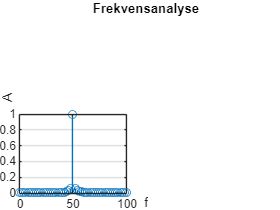

stem(f,X1mag)
grid
xlabel('f')
ylabel('A')
title("Frekvensanalyse")
xlim([0, 100])

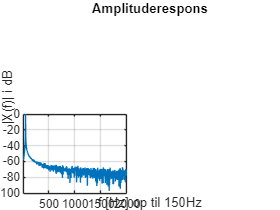


plot(f(1:Ndft/2),20*log10(X1mag(1:Ndft/2)))
grid
xlabel('f [Hz] op til 150Hz')
ylabel('|X(f)| i dB')
title('Amplituderespons')
xlim([10, 2000])

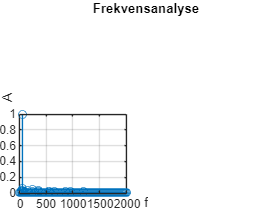


stem(f,X2mag)
grid
xlabel('f')
ylabel('A')
title("Frekvensanalyse")
xlim([0, 2000])

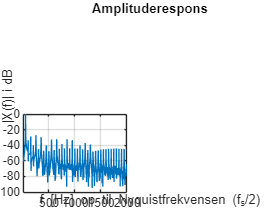


plot(f(1:Ndft/2),20*log10(X2mag(1:Ndft/2)))
grid
xlabel('f [Hz] op til Nyquistfrekvensen (f_s/2)')
ylabel('|X(f)| i dB')
title('Amplituderespons')
xlim([10, 2000])

### Design og implementering af IIR filter

Vi designer et IIR filtre til at dæmpe støjen. Vi ved at frekvensen er 50.11 Hz i det her tilfælde, men det kunne ske at frekvensen var højere, måske endda op til 60Hz som er standard vest for atlanten. Vi ved at højere frekvenskomponenter er heltals multiplikationer af grundfrekvensen, så vi vil gerne have filtreret 100Hz og derover væk. 

Et 2. ordens IIR filter er givet ved: 


$$y\left(n\right)=b_0 x\left(n\right)+b_1 x\left(n-1\right)+b_2 x\left(n-2\right)+a_1 y\left(n-1\right)+a_2 y\left(n-2\right)$$


Efter z transformation får vi:


$$Y\left(z\right)=$$

$$b_0 X\left(z\right)+b_1 X\left(z\right)z^{-1} +b_2 X\left(z\right)z^{-2} +a_1 Y\left(z\right)z^{-1} +a_2 Y\left(z\right)z^{-2}$$


Samlet overføringsfunktion


$$\frac{Y\left(z\right)}{X\left(z\right)}=$$

$$\frac{b_0 +b_1 z^{-1} +b_2 z^{-2} }{1-a_1 z^{-1} -a_2 z^{-2} }$$


Vi finder a og b koefficienter med matlabs indbyggede filter funktioner. I opgaven kommer vi til at bruge 2. ordens filtre af typerne Butterworth, Elliptisk og chebyshev.

Vi har valgt at bruge et Chebyshev type I filter da det er mere effektivt ved lavere ordner, frem for et type 2. Der vil dog forekomme ripple i passbåndet.

[Lyons, R. G. "Understanding digital signal processing " 3rd edition, side 895]

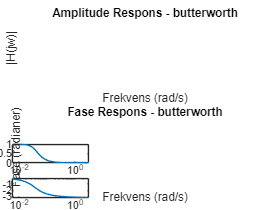

% Parametre
n = 2;              % Filterorden
Rp = 1;             % Maksimal ripple i passbåndet (dB)
Rs = 60;            % Minimum dæmpning i stopbåndet (dB)
fc = 61;            % Knækfrekvens i Hz
fn = fc / (fs/2);   % Normaliseret frekvens



[b, a] = butter(n,fn,"low");
x1_butter_filt = filter(b,a,x1);
x2_butter_filt = filter(b,a,x2);
[H1, W1] = freqz(b,a);

% Plot amplitude respons
figure;
subplot(2,1,1);
semilogx(W1, abs(H1));  % Amplitude respons
title('Amplitude Respons - butterworth');
xlabel('Frekvens (rad/s)');
ylabel('|H(jw)|');
% Juster margener og mellemrum
set(gcf, 'Position', [100, 100, 800, 600]); % Figurens størrelse

% Plot fase respons
subplot(2,1,2);
semilogx(W1, angle(H1));  % Fase respons
title('Fase Respons - butterworth');
xlabel('Frekvens (rad/s)');
ylabel('Fase (radianer)');

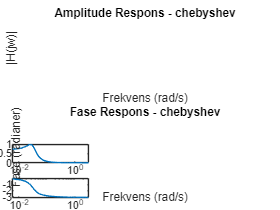

% Juster margener og mellemrum
set(gcf, 'Position', [100, 100, 800, 600]); % Figurens størrelse
    
[b, a] = cheby1(n, 3, fn, 'low');
x1_cheby_filt = filter(b,a,x1);
x2_cheby_filt = filter(b,a,x2);
[H2, W2] = freqz(b,a);

figure;
subplot(2,1,1);
semilogx(W2, abs(H2));  % Amplitude respons
title('Amplitude Respons - chebyshev');
xlabel('Frekvens (rad/s)');
ylabel('|H(jw)|');
% Juster margener og mellemrum
set(gcf, 'Position', [100, 100, 800, 600]); % Figurens størrelse

% Plot fase respons
subplot(2,1,2);
semilogx(W2, angle(H2));  % Fase respons
title('Fase Respons - chebyshev');
xlabel('Frekvens (rad/s)');
ylabel('Fase (radianer)');

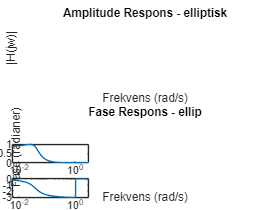

% Juster margener og mellemrum
set(gcf, 'Position', [100, 100, 800, 600]); % Figurens størrelse

[b, a] = ellip(n, Rp, Rs, fn, 'low');
x1_ellip_filt = filter(b,a,x1);
x2_ellip_filt = filter(b,a,x2);
[H3, W3] = freqz(b,a);

figure;
subplot(2,1,1);
semilogx(W3, abs(H3));  % Amplitude respons
title('Amplitude Respons - elliptisk');
xlabel('Frekvens (rad/s)');
ylabel('|H(jw)|');
% Juster margener og mellemrum
set(gcf, 'Position', [100, 100, 800, 600]); % Figurens størrelse

% Plot fase respons
subplot(2,1,2);
semilogx(W3, angle(H3));  % Fase respons
title('Fase Respons - ellip');
xlabel('Frekvens (rad/s)');
ylabel('Fase (radianer)');

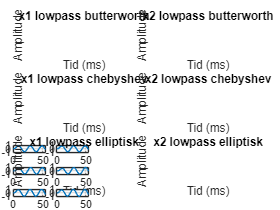

% Juster margener og mellemrum
set(gcf, 'Position', [100, 100, 800, 600]); % Figurens størrelse


% x1 butterworth
figure;
subplot(3,2,1);
plot(t * 1000, x1_butter_filt); % t konverteres til millisekunder
title(['x1 lowpass butterworth']);
xlabel('Tid (ms)');
ylabel('Amplitude');
grid on;
xlim([0, 55]); 
% Juster margener og mellemrum
set(gcf, 'Position', [100, 100, 800, 600]); % Figurens størrelse
    
% x2 butterworth
subplot(3,2,2);
plot(t * 1000, x2_butter_filt); % t konverteres til millisekunder
title(['x2 lowpass butterworth']);
xlabel('Tid (ms)');
ylabel('Amplitude');
grid on;
xlim([0, 55]); 
% Juster margener og mellemrum
set(gcf, 'Position', [100, 100, 800, 600]); % Figurens størrelse

% x1 chebyshev
subplot(3,2,3);
plot(t * 1000, x1_cheby_filt);
title(['x1 lowpass chebyshev']);
xlabel('Tid (ms)');
ylabel('Amplitude');
grid on;
xlim([0, 55]);
% Juster margener og mellemrum
set(gcf, 'Position', [100, 100, 800, 600]); % Figurens størrelse

% x2 chebyshev
subplot(3,2,4);
plot(t * 1000, x2_cheby_filt);
title(['x2 lowpass chebyshev']);
xlabel('Tid (ms)');
ylabel('Amplitude');
grid on;
xlim([0, 55]);
% Juster margener og mellemrum
set(gcf, 'Position', [100, 100, 800, 600]); % Figurens størrelse

% x1 Elliptisk
subplot(3,2,5);
plot(t * 1000, x1_ellip_filt);
title(['x1 lowpass elliptisk']);
xlabel('Tid (ms)');
ylabel('Amplitude');
grid on;
xlim([0, 55]);
% Juster margener og mellemrum
set(gcf, 'Position', [100, 100, 800, 600]); % Figurens størrelse

% x1 Elliptisk
subplot(3,2,6);
plot(t * 1000, x2_ellip_filt);
title(['x2 lowpass elliptisk']);
xlabel('Tid (ms)');
ylabel('Amplitude');
grid on;
xlim([0, 55]);

% Juster margener og mellemrum
set(gcf, 'Position', [100, 100, 800, 600]); % Figurens størrelse

Når vi sammenligner de 3 filtre, kan man tydeligt se at butterworth filteret skiller sig ud ift. elliptisk og chebyshev. Der forekommer ingen ripple effekt i passbåndet i butterworth, men til gengæld har den en langsommere frekvensrespons. Butterworth er derfor ikke så responsivt som chebyshev og elliptisk filter 

Som en lille ekstra undersøgelse har vi til sammenligning lavet et FIR filter, for at se hvor mange ordener vi skal bruge, for at opnå ca. det samme signal (øjemål). Der når vi helt op på et 60. ordens filter for at opnå et signal der ligner det ikke støjfyldte signal. Til gengæld ser det ud som om at vi har et større delay i et 2. ordens IIR filter frem for et 60. ordens FIR filter.

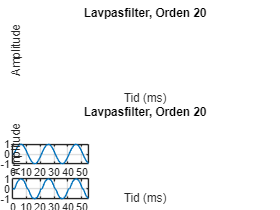

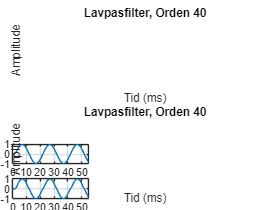

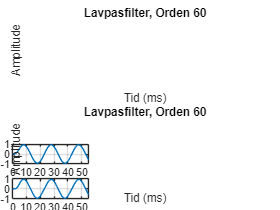

orders = [20, 40, 60]; % Filterordener

for N = orders
    
    % Design filter
    b = fir1(N, fn, 'low'); 
    x1_fir_filter = filter(b, 1, x1);
    x2_fir_filter = filter(b,1,x2);

    % Plot
    figure;
    subplot(2,1,1);
    plot(t * 1000, x1_fir_filter); % t konverteres til millisekunder
    title(['Lavpasfilter, Orden ', num2str(N)]);
    xlabel('Tid (ms)');
    ylabel('Amplitude');
    grid on;
    % Begrænsning af tidsaksen til 0-55 ms
    xlim([0, 55]); % i millisekunder
    % Juster margener og mellemrum
set(gcf, 'Position', [100, 100, 800, 600]); % Figurens størrelse
    
    % Plot
    subplot(2,1,2);
    plot(t * 1000, x2_fir_filter); % t konverteres til millisekunder
    title(['Lavpasfilter, Orden ', num2str(N)]);
    xlabel('Tid (ms)');
    ylabel('Amplitude');
    grid on;
    % Juster margener og mellemrum
set(gcf, 'Position', [100, 100, 800, 600]); % Figurens størrelse

    % Begrænsning af tidsaksen til 0-55 ms
    xlim([0, 55]); % i millisekunder
end

### Zero crossing algoritme

Vi har implementeret den givne algoritme til beregning af Zero crossing

% Beregning af nulgennemgange for de filtrerede signaler
zc_x1_unfiltered = find(diff(sign(x1)) ~= 0)

zc_x1_unfiltered =          100         200         299         400         500         599         699         799         899         998        1098        1198        1298        1397        1497        1597        1697        1797        1896        1996        2096        2195        2295        2395        2495        2595        2694        2794        2894        2994        3094        3194        3293        3393        3493        3593        3692        3792        3892        3991        4091        4191        4291        4391        4491        4590        4690        4790        4890        4989



zc_butter_x1 = find(diff(sign(x1_butter_filt)) ~= 0) % Indeks for nulgennemgange i x1_filtered

zc_butter_x1 =          141         241         341         441         541         640         740         840         940        1039        1139        1239        1339        1439        1538        1638        1738        1838        1938        2037        2137        2237        2337        2436        2536        2636        2736        2835        2935        3035        3135        3235        3334        3434        3534        3634        3734        3833        3933        4033        4133        4232        4332        4432        4532        4632        4731        4831        4931


zc_butter_x2 = find(diff(sign(x2_butter_filt)) ~= 0); % Indeks for nulgennemgange i x2_filtered

zc_cheby_x1 = find(diff(sign(x1_cheby_filt)) ~= 0); 
zc_cheby_x2 = find(diff(sign(x2_cheby_filt)) ~= 0); 

zc_ellip_x1 = find(diff(sign(x1_ellip_filt)) ~= 0); 
zc_ellip_x2 = find(diff(sign(x2_ellip_filt)) ~= 0); 

% Kun tælle fulde perioder (hver anden nul-gennemgang)
zc_x1_unfiltered_full = zc_butter_x1(1:2:numel(zc_x1_unfiltered)); 

zc_x1_butter_full = zc_butter_x1(1:2:numel(zc_butter_x1)); 
zc_x2_butter_full = zc_butter_x2(1:2:numel(zc_butter_x2));

zc_x1_cheby_full = zc_cheby_x1(1:2:numel(zc_cheby_x1)); 
zc_x2_cheby_full = zc_cheby_x2(1:2:numel(zc_cheby_x2));

zc_x1_ellip_full = zc_ellip_x1(1:2:numel(zc_ellip_x1)); 
zc_x2_ellip_full = zc_ellip_x2(1:2:numel(zc_ellip_x2));

% Beregning af perioder med interpolation for fulde perioder
T_x1_unfiltered = [];
maxLength = min(length(zc_x1_unfiltered)-1, length(zc_x1_unfiltered_full)-1);
for i = 1:maxLength
    n1 = zc_x1_unfiltered_full(i);
    n2 = zc_x1_unfiltered_full(i+1);

    x1_n1 = x1(n1);
    x1_n2 = x1(n1 + 1);

    frac = abs(x1_n1) / (abs(x1_n1) + abs(x1_n2));
    T_interpoleret = frac * Ts;
    T_x1_unfiltered(i) = (n2 - n1) * Ts - T_interpoleret;
end

T_x1_butter = [];
for i = 1:length(zc_x1_butter_full)-1
    n1 = zc_x1_butter_full(i); n2 = zc_x1_butter_full(i+1);
    x1_n1 = x1_butter_filt(n1);
    x1_n2 = x1_butter_filt(n1 + 1);
    frac = abs(x1_n1) / (abs(x1_n1) + abs(x1_n2));
    T_interpoleret = frac * Ts;
    T_x1_butter(i) = (n2 - n1) * Ts - T_interpoleret;
end

T_x2_butter = [];
for i = 1:length(zc_x2_butter_full)-1
    n1 = zc_x2_butter_full(i); n2 = zc_x2_butter_full(i+1);
    x2_n1 = x2_butter_filt(n1);
    x2_n2 = x2_butter_filt(n1 + 1);
    frac = abs(x2_n1) / (abs(x2_n1) + abs(x2_n2));
    T_interpoleret = frac * Ts;
    T_x2_butter(i) = (n2 - n1) * Ts - T_interpoleret;
end

T_x1_cheby = [];
for i = 1:length(zc_x1_cheby_full)-1
    n1 = zc_x1_cheby_full(i); n2 = zc_x1_cheby_full(i+1);
    x1_n1 = x1_cheby_filt(n1);
    x1_n2 = x1_cheby_filt(n1 + 1);
    frac = abs(x1_n1) / (abs(x1_n1) + abs(x1_n2));
    T_interpoleret = frac * Ts;
    T_x1_cheby(i) = (n2 - n1) * Ts - T_interpoleret;
end

T_x2_cheby = [];
for i = 1:length(zc_x2_cheby_full)-1
    n1 = zc_x2_cheby_full(i); n2 = zc_x2_cheby_full(i+1);
    x2_n1 = x2_cheby_filt(n1);
    x2_n2 = x2_cheby_filt(n1 + 1);
    frac = abs(x2_n1) / (abs(x2_n1) + abs(x2_n2));
    T_interpoleret = frac * Ts;
    T_x2_cheby(i) = (n2 - n1) * Ts - T_interpoleret;
end

T_x1_ellip = [];
for i = 1:length(zc_x1_ellip_full)-1
    n1 = zc_x1_ellip_full(i); n2 = zc_x1_ellip_full(i+1);
    x1_n1 = x1_ellip_filt(n1);
    x1_n2 = x1_ellip_filt(n1 + 1);
    frac = abs(x1_n1) / (abs(x1_n1) + abs(x1_n2));
    T_interpoleret = frac * Ts;
    T_x1_ellip(i) = (n2 - n1) * Ts - T_interpoleret;
end

T_x2_ellip = [];
for i = 1:length(zc_x2_ellip_full)-1
    n1 = zc_x2_ellip_full(i); n2 = zc_x2_ellip_full(i+1);
    x2_n1 = x2_ellip_filt(n1);
    x2_n2 = x2_ellip_filt(n1 + 1);
    frac = abs(x2_n1) / (abs(x2_n1) + abs(x2_n2));
    T_interpoleret = frac * Ts;
    T_x2_ellip(i) = (n2 - n1) * Ts - T_interpoleret;
end


% Beregning af gennemsnitsfrekvenser
f_x1_unfiltered_full = 1 ./ T_x1_unfiltered; % Frekvenser for x1
f_mean_x1_unfiltered_full = mean(f_x1_unfiltered_full);

f_x1_butter_full = 1 ./ T_x1_butter; % Frekvenser for x1_filtered
f_x2_butter_full = 1 ./ T_x2_butter; % Frekvenser for x2_filtered
f_mean_x1_butter_full = mean(f_x1_butter_full);
f_mean_x2_butter_full = mean(f_x2_butter_full);

f_x1_cheby_full = 1 ./ T_x1_cheby; 
f_x2_cheby_full = 1 ./ T_x2_cheby; 
f_mean_x1_cheby_full = mean(f_x1_cheby_full);
f_mean_x2_cheby_full = mean(f_x2_cheby_full);

f_x1_ellip_full = 1 ./ T_x1_ellip; 
f_x2_ellip_full = 1 ./ T_x2_ellip; 
f_mean_x1_ellip_full = mean(f_x1_ellip_full);
f_mean_x2_ellip_full = mean(f_x2_ellip_full);

% Resultater
disp(['f_x1_unfiltered (kun fulde perioder): ', num2str(f_mean_x1_unfiltered_full), ' Hz']);

f_x1_unfiltered (kun fulde perioder): 50.23 Hz



disp(['f_x1_butter (kun fulde perioder): ', num2str(f_mean_x1_butter_full), ' Hz']);

f_x1_butter (kun fulde perioder): 50.2168 Hz


disp(['f_x2_butter (kun fulde perioder): ', num2str(f_mean_x2_butter_full), ' Hz']);

f_x2_butter (kun fulde perioder): 49.9845 Hz



disp(['f_x1_cheby (kun fulde perioder): ', num2str(f_mean_x1_cheby_full), ' Hz']);

f_x1_cheby (kun fulde perioder): 50.1945 Hz


disp(['f_x2_cheby (kun fulde perioder): ', num2str(f_mean_x2_cheby_full), ' Hz']);

f_x2_cheby (kun fulde perioder): 49.9305 Hz



disp(['f_x1_ellip (kun fulde perioder): ', num2str(f_mean_x1_ellip_full), ' Hz']);

f_x1_ellip (kun fulde perioder): 50.2304 Hz


disp(['f_x2_ellip (kun fulde perioder): ', num2str(f_mean_x2_ellip_full), ' Hz']);

f_x2_ellip (kun fulde perioder): 50.0304 Hz


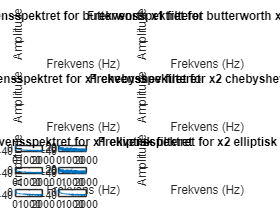


% Beregning af FFT for de filtrerede signaler, amplitude og fase


X1_filt_butter = fft(x1_butter_filt, Ndft);
X1mag_butter = abs(X1)*(2/N); % Vi ganger med 2/N for at få korrekte amplitude
X1mag_butter(1)=X1mag_butter(1)/2;   % Finder korrekt DC værdi

X2_filt_butter = fft(x2_butter_filt, Ndft);
X2mag_butter = abs(X2)*(2/N); % Vi ganger med 2/N for at få korrekte amplitude
X2mag_butter(1)=X2mag_butter(1)/2;   % Finder korrekt DC værdi

X1_filt_cheby = fft(x1_cheby_filt, Ndft);
X1mag_cheby = abs(X1)*(2/N); % Vi ganger med 2/N for at få korrekte amplitude
X1mag_cheby(1)=X1mag_cheby(1)/2;   % Finder korrekt DC værdi

X2_filt_cheby = fft(x2_cheby_filt, Ndft);
X2mag_cheby = abs(X2)*(2/N); % Vi ganger med 2/N for at få korrekte amplitude
X2mag_cheby(1)=X2mag_cheby(1)/2;   % Finder korrekt DC værdi

X1_filt_ellip = fft(x1_ellip_filt, Ndft);
X1mag_ellip = abs(X1)*(2/N); % Vi ganger med 2/N for at få korrekte amplitude
X1mag_ellip(1)=X1mag_ellip(1)/2;   % Finder korrekt DC værdi

X2_filt_ellip = fft(x2_ellip_filt, Ndft);
X2mag_ellip = abs(X2)*(2/N); % Vi ganger med 2/N for at få korrekte amplitude
X2mag_ellip(1)=X2mag_ellip(1)/2;   % Finder korrekt DC værdi

% Definer frekvensakse
f_axis = (0:Ndft-1) * (fs / Ndft); % Frekvensakse i Hz

% Plot af frekvensspektret
figure;
subplot(3,2,1);
plot(f(1:Ndft/2),20*log10(X1mag_butter(1:Ndft/2)));
xlabel('Frekvens (Hz)');
ylabel('Amplitude');
title('Frekvensspektret for butterworth x1 filteret');
xlim([0 2000]); % Fokus på lave frekvenser
% Juster margener og mellemrum
set(gcf, 'Position', [100, 100, 800, 600]); % Figurens størrelse

subplot(3,2,2);
plot(f(1:Ndft/2),20*log10(X2mag_butter(1:Ndft/2)));
xlabel('Frekvens (Hz)');
ylabel('Amplitude');
title('Frekvensspektret for butterworth x2 filteret');
xlim([0 2000]);
% Juster margener og mellemrum
set(gcf, 'Position', [100, 100, 800, 600]); % Figurens størrelse

subplot(3,2,3);
plot(f(1:Ndft/2),20*log10(X1mag_cheby(1:Ndft/2)));
xlabel('Frekvens (Hz)');
ylabel('Amplitude');
title('Frekvensspektret for x1 chebyshev filteret');
xlim([0 2000]); 
% Juster margener og mellemrum
set(gcf, 'Position', [100, 100, 800, 600]); % Figurens størrelse

subplot(3,2,4);
plot(f(1:Ndft/2),20*log10(X2mag_cheby(1:Ndft/2)));
xlabel('Frekvens (Hz)');
ylabel('Amplitude');
title('Frekvensspektret for x2 chebyshev filteret');
xlim([0 2000]);
% Juster margener og mellemrum
set(gcf, 'Position', [100, 100, 800, 600]); % Figurens størrelse

subplot(3,2,5);
plot(f(1:Ndft/2),20*log10(X1mag_ellip(1:Ndft/2)));
xlabel('Frekvens (Hz)');
ylabel('Amplitude');
title('Frekvensspektret for x1 elliptisk filteret');
xlim([0 2000]);
% Juster margener og mellemrum
set(gcf, 'Position', [100, 100, 800, 600]); % Figurens størrelse

subplot(3,2,6);
plot(f(1:Ndft/2),20*log10(X1mag_ellip(1:Ndft/2)));
xlabel('Frekvens (Hz)');
ylabel('Amplitude');
title('Frekvensspektret for x2 elliptisk filteret');
xlim([0 2000]);

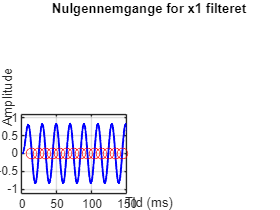

% Juster margener og mellemrum
set(gcf, 'Position', [100, 100, 800, 600]); % Figurens størrelse


% Plot af zero-crossings
figure;
plot(t * 1000, x1_butter_filt, 'b-', 'LineWidth', 1.5); hold on;
plot(zc_butter_x1 * Ts * 1000, zeros(size(zc_butter_x1)), 'ro', 'MarkerSize', 8); % Marker nulgennemgange
xlabel('Tid (ms)');
ylabel('Amplitude');
title('Nulgennemgange for x1 filteret');
grid on;
xlim([0 150]);
ylim([-1.1 1.1]);


% Forventet frekvens
f_ideal = 50.1111; % Hz

% Beregning af absolut afvigelse
delta_f_x1_unfiltered = abs(f_mean_x1_unfiltered_full - f_ideal);

delta_f_x1_butter = abs(f_mean_x1_butter_full - f_ideal); % Absolut afvigelse for x1
delta_f_x2_butter = abs(f_mean_x2_butter_full - f_ideal); % Absolut afvigelse for x2

delta_f_x1_cheby = abs(f_mean_x1_cheby_full - f_ideal);
delta_f_x2_cheby = abs(f_mean_x2_cheby_full - f_ideal); 

delta_f_x1_ellip = abs(f_mean_x1_ellip_full - f_ideal); 
delta_f_x2_ellip = abs(f_mean_x2_ellip_full - f_ideal); 

% Udskriv resultater
disp(['Afvigelse for f_x1_unfiltered: ', num2str(delta_f_x1_unfiltered), ' Hz (', num2str(delta_f_x1_unfiltered * 1000), ' mHz)']);

Afvigelse for f_x1_unfiltered: 0.11889 Hz (118.8872 mHz)



disp(['Afvigelse for f_x1_butter: ', num2str(delta_f_x1_butter), ' Hz (', num2str(delta_f_x1_butter * 1000), ' mHz)']);

Afvigelse for f_x1_butter: 0.10572 Hz (105.7191 mHz)


disp(['Afvigelse for f_x2_butter: ', num2str(delta_f_x2_butter), ' Hz (', num2str(delta_f_x2_butter * 1000), ' mHz)']);

Afvigelse for f_x2_butter: 0.12656 Hz (126.5631 mHz)



disp(['Afvigelse for f_x1_cheby: ', num2str(delta_f_x1_cheby), ' Hz (', num2str(delta_f_x1_cheby * 1000), ' mHz)']);

Afvigelse for f_x1_cheby: 0.08343 Hz (83.4298 mHz)


disp(['Afvigelse for f_x2_cheby: ', num2str(delta_f_x2_cheby), ' Hz (', num2str(delta_f_x2_cheby * 1000), ' mHz)']);

Afvigelse for f_x2_cheby: 0.18062 Hz (180.6183 mHz)



disp(['Afvigelse for f_x1_ellip: ', num2str(delta_f_x1_ellip), ' Hz (', num2str(delta_f_x1_ellip * 1000), ' mHz)']);

Afvigelse for f_x1_ellip: 0.11927 Hz (119.2712 mHz)


disp(['Afvigelse for f_x2_ellip: ', num2str(delta_f_x2_ellip), ' Hz (', num2str(delta_f_x2_ellip * 1000), ' mHz)']);

Afvigelse for f_x2_ellip: 0.080696 Hz (80.6964 mHz)


Efter at have beregnet afvigelserne, kan vi se at den mindste afvigelse er for det elliptiske filter, hvor vi har en afvigelse på 80,696 mHz, altså ca. 8 gange højere end den maksimalt ønskede afvigelse på +- 10mHz. Det må betragtes som held at vi overhovedet kom så tæt på med beregningen, da beregningen på det rene 50,11Hz sinussignal havde en afvigelse på 118mHz.

### Konklusion

I denne rapport blev der udviklet og implementeret et 2. ordens IIR lavpasfilter for at filtrere et støjfyldt signal for at undersøge om vi kunne opfylde kravene til opgaven. Efter at have analyseret signalet både i tids- og frekvensdomænet, kunne vi 39 harmoniske funktioner.

Vi benyttede os af 3 forskellige typer lavpasfiltre (Butterworth, Chebyshev type 1 og Elliptisk), for at se forskellige IIR-filtres evne til at dæmpe højfrekvent støj. Sammenlignet med FIR-filtre, fandt vi at IIR-filtre krævede væsentligt færre ordener for at opnå en tilsvarende filtrering, hvilket i praksis vil spare os for mange udregninger, men også resultere i et billigere produkt, det det ikke vil kræve lige så mange komponenter at lave. 

Ved hjælp af Zero Crossing-algoritmen kunne grundfrekvenserne af de filtrerede signaler beregnes. Vi kunne dog ikke opnå kravet på en maksimal afvigelse på 10mHz, med de givne signaler. En højere samplerate eller et større antal samples ville kunne hjælpe os til at opfylde afvigelseskravet.